# Liquid Level Control Question: 6

Mohammad Khaled Gamal Ali Sec : 2 BN : 14

clc; clear; close all;

## Requirements


$$O\ldotp S\ldotp =5%,T_s =5s,e_{\textrm{ss}} =5%$$


OS=0.05;        T_Settle=5;       Ess=0.05;
zeta=fzero(@(x) OS-exp(-pi*x/sqrt(1-x^2)),0.5);
w_n=4/T_Settle/zeta;

## System definition


$$\textrm{For}\;G_p =\frac{K_{\textrm{amp}} }{\tau \;s+1}$$


s=tf('s');
tau=4.35;        K_amp=4;        H=0.1;
Gp=K_amp/(tau*s+1);

## Controller


$$\textrm{Let}\;G_c =\frac{K_c \left(\tau \;s+1\right)}{s^2 +\textrm{xs}+y}$$


K_c=(1-Ess)*w_n^2/K_amp;
x=2*zeta*w_n;
y=w_n^2-K_amp*H*K_c;
G_c=K_c*(tau*s+1)/(s^2+x*s+y);

## Continuous


$$\begin{array}{l}
\textrm{Forwad}\;\textrm{Path}\;\textrm{Function}:G_{\textrm{fp}} =G_c \cdot G_p \\
\textrm{Closed}\;\textrm{Loop}\;\textrm{Transfer}\;\textrm{Function}:G_{\textrm{cl}} =\frac{G_c \cdot G_p }{1+G_c \cdot G_p \cdot H}
\end{array}$$


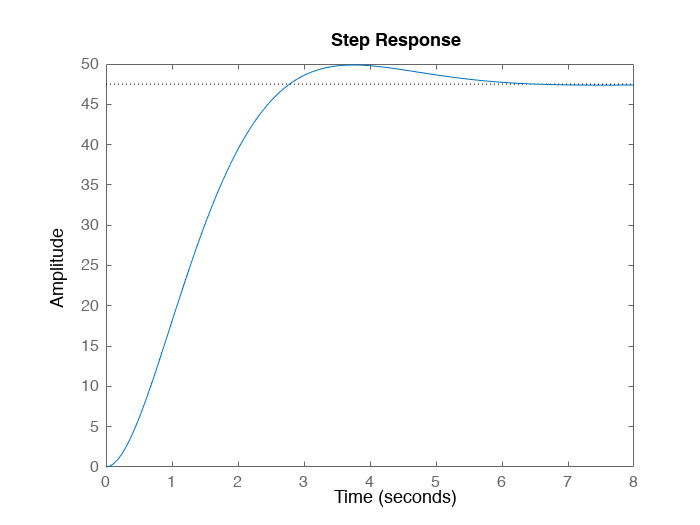

G_fp=G_c*Gp;
G_c=feedback(G_fp,H);
Info_Continous=stepinfo(G_c);
step(G_c*50);       hold on;

## **Optimum sampling time determination**

Typically for Arduinos (UNO, Nano, Mega) the minimums sampling time to read an analog input is 0.0001 seconds so we will take that as our minimum available sampling time and for our system we found out earlier that the maximum allowable sampling time can be obtained from $T_s |_{\max } \le \frac{\tau }{10}$ so our maxium available value for the sampling time is $\frac{\tau }{10}=0\ldotp 435\;\mathrm{seconds}$.

The criteria we are trying to satisfy here is for the relative error between the continous and digitalized system to be less than $0\ldotp 01$for the settling time and for the precentage overshoot.

T=linspace(0.1*tau,0.0001,15);
G_z=cell(length(T),1);   G_c=cell(length(T),1);   Sys_Info=cell(length(T),1);
Err=1e-2;       T_sampling=0;
for i=1:length(T)
    G_z{i}=c2d(G_fp,T(i));
    G_c{i}=feedback(G_z{i},H);
    Sys_Info{i}=stepinfo(G_c{i});
    if abs(Info_Continous.SettlingTime-Sys_Info{i}.SettlingTime)...
          /Info_Continous.SettlingTime<Err && abs(Info_Continous.Overshoot...
            -Sys_Info{i}.Overshoot)/Info_Continous.Overshoot<Err
        T_sampling=T(i);
        OS=Sys_Info{i}.Overshoot;
        T_Settle=Sys_Info{i}.SettlingTime;
        break
    end
end

## **Results**

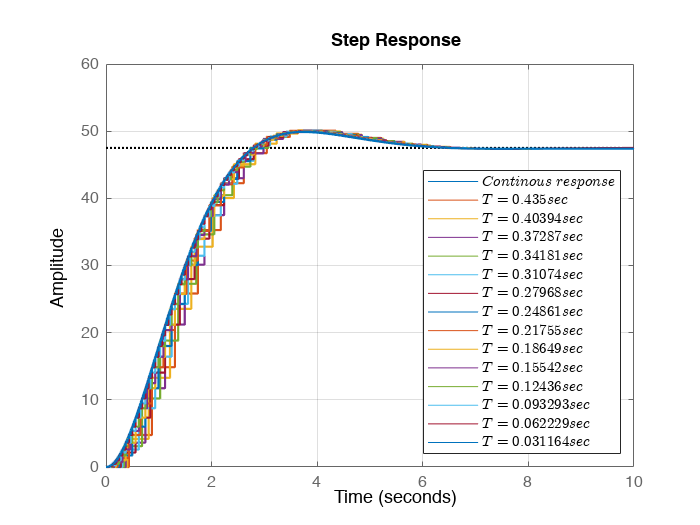

T_sampling = 0.0312

OS = 5.0359

T_Settle = 5.1733

D_z =
 
       0.0012093 z (z-0.9929)
  ---------------------------------
  (z-0.9929) (z^2 - 1.95z + 0.9514)
 
Sample time: 0.031164 seconds
Discrete-time zero/pole/gain model.



if T_sampling==0
    disp('No optimum sampling time found, try another range of T');
else
    index=find(T==T_sampling);
    legendstring=cell(1,index+1);
    legendstring{1}='$Continous\;response$';
    for i=1:index
    legendstring{i+1}=['$T= ', num2str(T(i)), 'sec$'];
    step(G_c{i}*50);
    end
    D_z=zpk(c2d(G_fp,T_sampling,'impulse'));
    hold off; grid on; box on;
    set(findall(gcf,'Type','line'),'LineWidth',1.3)
    legend(legendstring,'interpreter','latex','Location','SouthEast')
    display(T_sampling); display(OS); 
    display(T_Settle);         display(D_z);
end

## **Conclusion**

For the range we defined earlier $0\ldotp 0001\le T_s \le \frac{\tau }{10}$ the maximum minimum sampling time is $T_s =0\ldotp 031164\;\sec$